# SIS Dynamics on Networks — Live Script Overview

This project studies the **Susceptible–Infected–Susceptible (SIS)** epidemic process on networks, implemented in MATLAB as a **Live Script (.mlx)** for clarity and reproducibility.

## Model overview

We consider a network of N nodes with adjacency matrix A = (Aᵢⱼ), where Aᵢⱼ = 1 if an edge exists between nodes i and j, and Aᵢⱼ = 0 otherwise. The state of node i at time t is xᵢ(t) ∈ {0,1}, with 1 = infected and 0 = susceptible.


$$\[
x_i(t) \in \{0,1\}, \quad
x_i(t) = 
\begin{cases}
1 & \text{infected}, \\
0 & \text{susceptible}.
\end{cases}
\]
$$


The SIS dynamics use infection rate β > 0 and recovery rate μ > 0:

- **Recovery:** if xᵢ(t) = 1, node i becomes susceptible at rate μ.

- **Infection:** if xᵢ(t) = 0 and it has kᵢ(t) = ∑ⱼ Aᵢⱼ xⱼ(t) infected neighbors, then it becomes infected at rate β·kᵢ(t).

A mean-field description for the infection probability pᵢ(t) = 𝐄[xᵢ(t)] is:

**Equation cell (mean-field SIS):**


$$\frac{dp_i}{dt} = -\mu\,p_i(t) + \beta \,\bigl(1 - p_i(t)\bigr)\sum_{j=1}^{N} A_{ij}\, p_j(t)$$


The epidemic threshold relates to the largest eigenvalue λₘₐₓ(A) of A: persistence typically requires,


$$\frac{\beta}{\mu} > \frac{1}{\lambda_{\max}(A)}$$


*References (enter in a Text cell):*

Erdős & Rényi (1960); May & Lloyd (2001); Pastor-Satorras & Vespignani (2001).

## Live Script (.mlx) structure

- **Setup:** random seed and parameters (N, β, μ, p), plus simple toggles for plots/exports.

- **Network generation:** construct Erdős–Rényi (ER) graph G(N,p) and adjacency Aᵢⱼ.

- **Model construction:** build linear system matrices and nonlinear interaction terms.

- **Linear spectral analysis:** extract leading mode; set initial condition.

- **Full-system simulation:** integrate the SIS dynamics (ODE solver).

- **Spectral submanifold (SSM) reductions:** compute reduced dynamics for selected orders.

- **Plots (optional, per section):** mean prevalence ⟨I⟩(t) and node trajectories, comparing SSM vs full.

- **Convergence diagnostics:** roots of analytic approximants a(ρ) for convergence.

Each item is an independent **section (%%)** in the .mlx.

## Extending beyond ER networks

The adjacency matrix A is the only network-dependent input. Replace A with another topology (e.g., scale-free, small-world, lattice, empirical networks) and reuse the same pipeline without code changes downstream.

## One-parameter bifurcation outline

Sweep a single parameter—typically β (or τ = β/μ). For each value, simulate to steady behavior and record the mean prevalence ⟨I⟩. Plot ⟨I⟩ vs β to expose thresholds and nonlinear transitions; compare to the spectral heuristic 1/λₘₐₓ(A).

## Error metrics 

In the next step, we will include metrics to quantify SSM vs full-system differences, e.g., mean-squared error (MSE) of ⟨I⟩(t) over time, node-wise deviations, and summary statistics (peak prevalence, time to extinction). You can paste those definitions here when ready.

**Note:** This Live Script requires the SSSMTool package (Spectral Submanifold Toolbox). Please ensure that SSSMTool and its dependencies are installed and on the MATLAB path before running the .mlx.

clearvars; close all; clc;
rng(0,'twister');

## (a) Parameters

N       = 200; K = 4; mu = 1.0; beta = 0.5;
p       = 2*K/(N-1);
orders  = [2, 10, 15, 20]; appr_order = max(orders);
initVal = 0.01; tf = 50; nsteps = 1000;

## (b) ER network

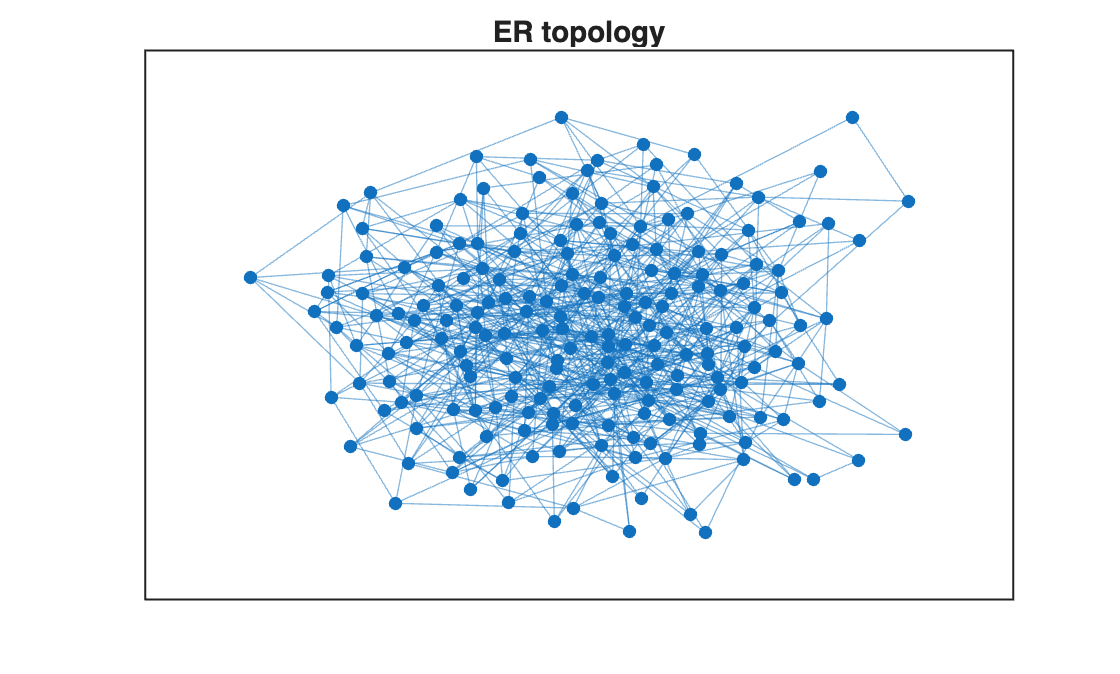

A = rand(N) < p; A = triu(A,1); A = A + A.';
G = graph(A);
figure; plot(G,'Layout','force','NodeLabel',{},'MarkerSize',4);
title('ER topology');

## (c) Build dynamical system

[MatA, MatB, MatF] = build_model(A,beta,mu);
DS = DynamicalSystem(1);
DS.A = MatA; DS.B = MatB; DS.fnl = MatF;
DS.Options.Emax=2; DS.Options.Nmax=max(orders);
DS.Options.notation='tensor'; DS.Options.sigma=1000;

## (d) Linear spectral analysis & init

[V,~,~] = DS.linear_spectral_analysis();


 The first 2 nonzero eigenvalues are given as 
    3.4314
    1.7273



q0      = initVal * sign(V(1,1));
z0_full = q0 * V(:,1);

## (e) Full system trajectory

[tRef,zRef] = time_integration_transient(DS,2*pi, ...
    'nSteps', nsteps/tf,'nCycles',tf,'integrationMethod','ode45', ...
    'outdof',1:N,'init',z0_full);

## (f) SSM trajectories

traj_all = cell(numel(orders),1);
R0_for_analytic = [];
for k = 1:numel(orders)
    ord = orders(k);
    S = SSM(DS);
    S.Options.paramStyle = 'graph';
    S.Options.reltol     = 100;
    S.Options.notation   = 'tensor';
    S.choose_E(1);
    [W0, R0] = S.compute_whisker(ord);
    if ord == max(orders), R0_for_analytic = R0; end

    traj_all{k} = transient_traj_on_auto_ssm( ...
        DS, 1, W0, R0, tf, nsteps, 1:N, [], q0);
end

sigma_out = 0
sigma_in = 0


Computing autonomous whisker at order 2
1 (near) inner resonance(s) detected at order 2
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 6.79E-01 MB


sigma_out = 0
sigma_in = 0


Computing autonomous whisker at order 2
1 (near) inner resonance(s) detected at order 2
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 6.79E-01 MB
Computing autonomous whisker at order 3
1 (near) inner resonance(s) detected at order 3
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 6.92E-01 MB
Computing autonomous whisker at order 4
1 (near) inner resonance(s) detected at order 4
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 7.02E-01 MB
Computing autonomous whisker at order 5
1 (near) inner resonance(s) detected at order 5
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 7.14E-01 MB
Computing autonomous whisker at order 6
1 (near) inner resonance(s) detected at order 6
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 7.28E-01 MB
Computing autonomous whisker at order 7
1 (near) inner resonance(s) detecte

sigma_out = 0
sigma_in = 0


Computing autonomous whisker at order 2
1 (near) inner resonance(s) detected at order 2
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 6.79E-01 MB
Computing autonomous whisker at order 3
1 (near) inner resonance(s) detected at order 3
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 6.92E-01 MB
Computing autonomous whisker at order 4
1 (near) inner resonance(s) detected at order 4
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 7.02E-01 MB
Computing autonomous whisker at order 5
1 (near) inner resonance(s) detected at order 5
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 7.14E-01 MB
Computing autonomous whisker at order 6
1 (near) inner resonance(s) detected at order 6
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 7.28E-01 MB
Computing autonomous whisker at order 7
1 (near) inner resonance(s) detecte

sigma_out = 0
sigma_in = 0


Computing autonomous whisker at order 2
1 (near) inner resonance(s) detected at order 2
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 6.79E-01 MB
Computing autonomous whisker at order 3
1 (near) inner resonance(s) detected at order 3
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 6.92E-01 MB
Computing autonomous whisker at order 4
1 (near) inner resonance(s) detected at order 4
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 7.02E-01 MB
Computing autonomous whisker at order 5
1 (near) inner resonance(s) detected at order 5
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 7.14E-01 MB
Computing autonomous whisker at order 6
1 (near) inner resonance(s) detected at order 6
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 7.28E-01 MB
Computing autonomous whisker at order 7
1 (near) inner resonance(s) detecte

## (g) Mean level dynamics

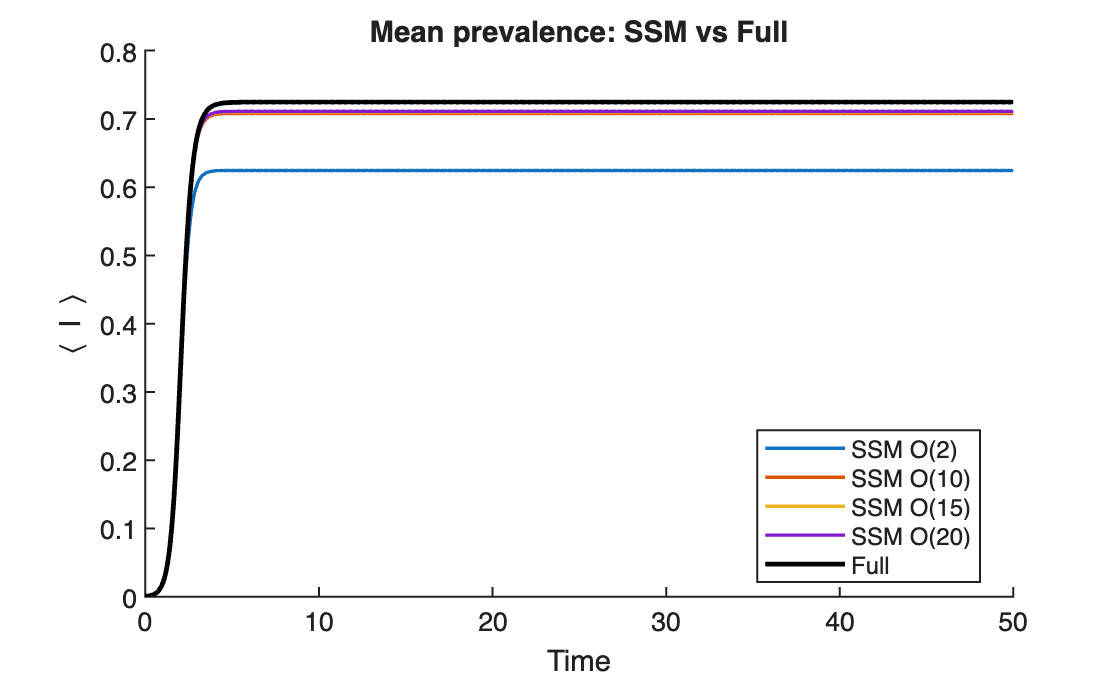

figure; hold on;
for k = 1:numel(orders)
    plot(traj_all{k}.time, mean(traj_all{k}.phy,2), 'LineWidth', 1.3, ...
        'DisplayName', sprintf('SSM O(%d)', orders(k)));
end
plot(tRef, mean(zRef,2), 'k-', 'LineWidth', 1.8, 'DisplayName', 'Full');
xlabel('Time'); ylabel('\langle I \rangle');
title('Mean prevalence: SSM vs Full');
legend('Location','best');
box off; grid off;

## (h) Mean level dynamics

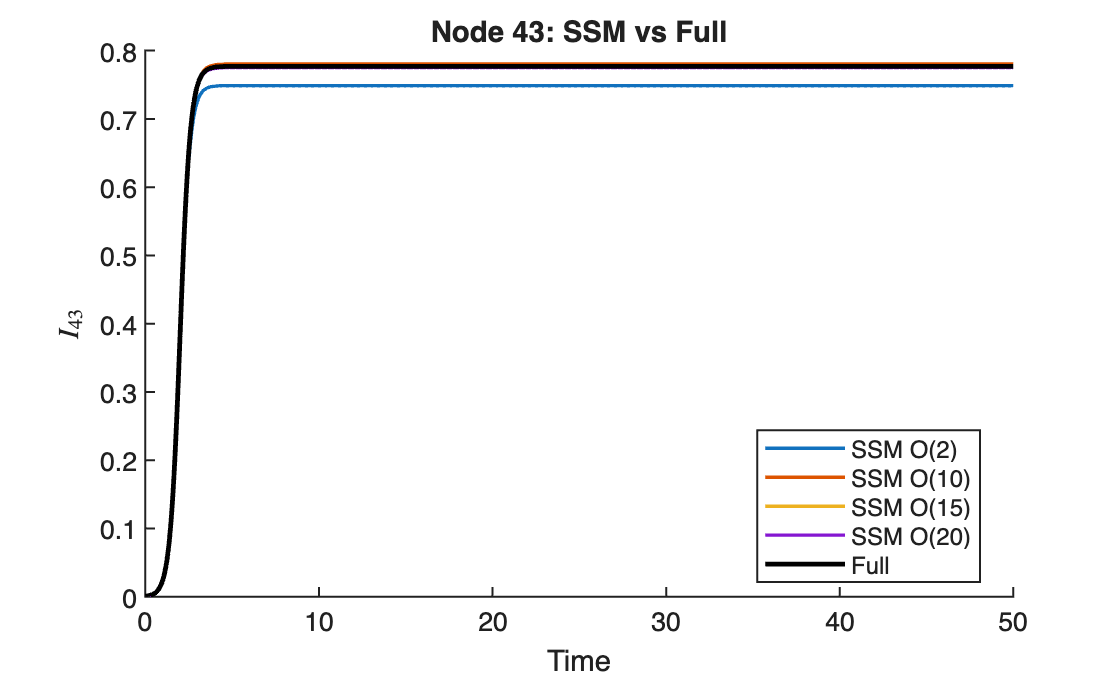

idnode = randi(N);  
figure; hold on;
for k = 1:numel(orders)
    plot(traj_all{k}.time, traj_all{k}.phy(:,idnode), 'LineWidth', 1.3, ...
        'DisplayName', sprintf('SSM O(%d)', orders(k)));
end
plot(tRef, zRef(:,idnode), 'k-', 'LineWidth', 1.8, 'DisplayName', 'Full');
xlabel('Time'); ylabel(sprintf('$I_{%d}$', idnode), 'Interpreter','latex');
title(sprintf('Node %d: SSM vs Full', idnode));
legend('Location','best');
box off; grid off;

## (i) Analytical domain

sigma_out = 0
sigma_in = 0
Computing autonomous whisker at order 2
1 (near) inner resonance(s) detected at order 2
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 6.79E-01 MB
Computing autonomous whisker at order 3
1 (near) inner resonance(s) detected at order 3
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 6.92E-01 MB
Computing autonomous whisker at order 4
1 (near) inner resonance(s) detected at order 4
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 7.02E-01 MB
Computing autonomous whisker at order 5
1 (near) inner resonance(s) detected at order 5
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 7.14E-01 MB
Computing autonomous whisker at order 6
1 (near) inner resonance(s) detected at order 6
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 7.28E-01 MB
Computing autonomous whisker at order 7
1 (near)

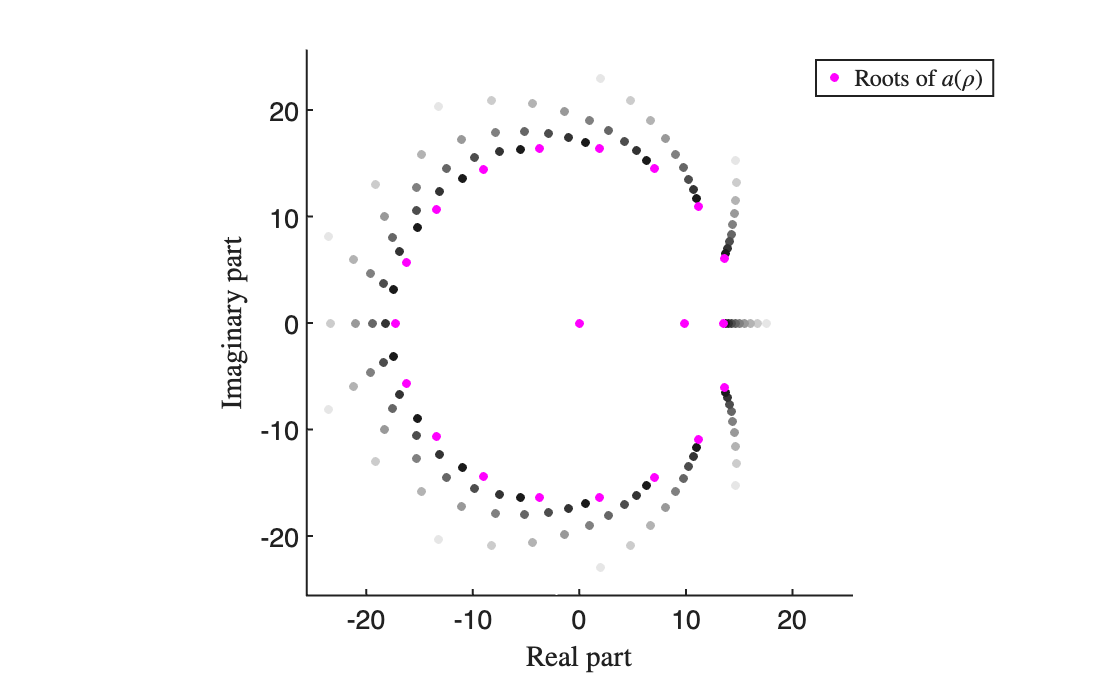

ord = appr_order;
S = SSM(DS); S.Options.paramStyle='graph'; S.Options.reltol=100; S.Options.notation='tensor';
S.choose_E(1); [~,R0] = S.compute_whisker(ord);figure; plot_analytical_domain(ord,R0);

## (j) Error metrics collection

tol         = 1e-4;
N           = size(zRef,2);
t_full      = tRef(:);
m_full      = mean(zRef,2);

deg_net     = degree(G);                 
eps_ss      = zeros(numel(orders), N);  
TSS_red     = zeros(numel(orders), N);   
MAE_node    = zeros(numel(orders),1);    
spatialCorr = zeros(numel(orders),1);    
err_time    = zeros(numel(orders), length(t_full));  
mse_mean    = zeros(numel(orders),1);   
x_full_ss = zRef(end,:);
TSS_full  = zeros(1,N);
for i = 1:N
    idx = find(abs(zRef(:,i) - x_full_ss(i)) < tol, 1, 'first');
    if isempty(idx), idx = length(t_full); end
    TSS_full(i) = t_full(idx);
end
for k = 1:numel(orders)
    t_red = traj_all{k}.time(:);
    Xr    = traj_all{k}.phy;                   
    Xr_on_full = interp1(t_red, Xr, t_full, 'linear', 'extrap'); 
    x_red_ss       = Xr_on_full(end,:);
    eps_ss(k, :)   = abs(x_full_ss - x_red_ss);         
    MAE_node(k)    = mean(eps_ss(k,:));                 
    spatialCorr(k) = corr(x_full_ss', x_red_ss');       
    x_red_native_ss = Xr(end,:);
    for i = 1:N
        idx = find(abs(Xr(:,i) - x_red_native_ss(i)) < tol, 1, 'first');
        if isempty(idx), idx = size(Xr,1); end
        TSS_red(k,i) = t_red(idx);
    end
    err_time(k,:)  = mean(abs(zRef - Xr_on_full), 2)';
    m_red          = mean(Xr_on_full, 2);
    mse_mean(k)    = mean( (m_red - m_full).^2 );
end
err_surface = err_time;

**1. MSE of mean prevalence**


$$\mathrm{MSE}_{\langle I\rangle}(o)
= \frac{1}{T}\int_{0}^{T}\big(\langle I\rangle_{\text{SSM}(o)}(t)-\langle I\rangle_{\text{full}}(t)\big)^{2}\,dt
\approx \frac{1}{M}\sum_{m=1}^{M}\big(m_o(t_m)-m_{\text{full}}(t_m)\big)^2,
$$


where $m_o(t)=\frac{1}{N}\sum_{i=1}^{N}x^{(o)}_i(t)
$

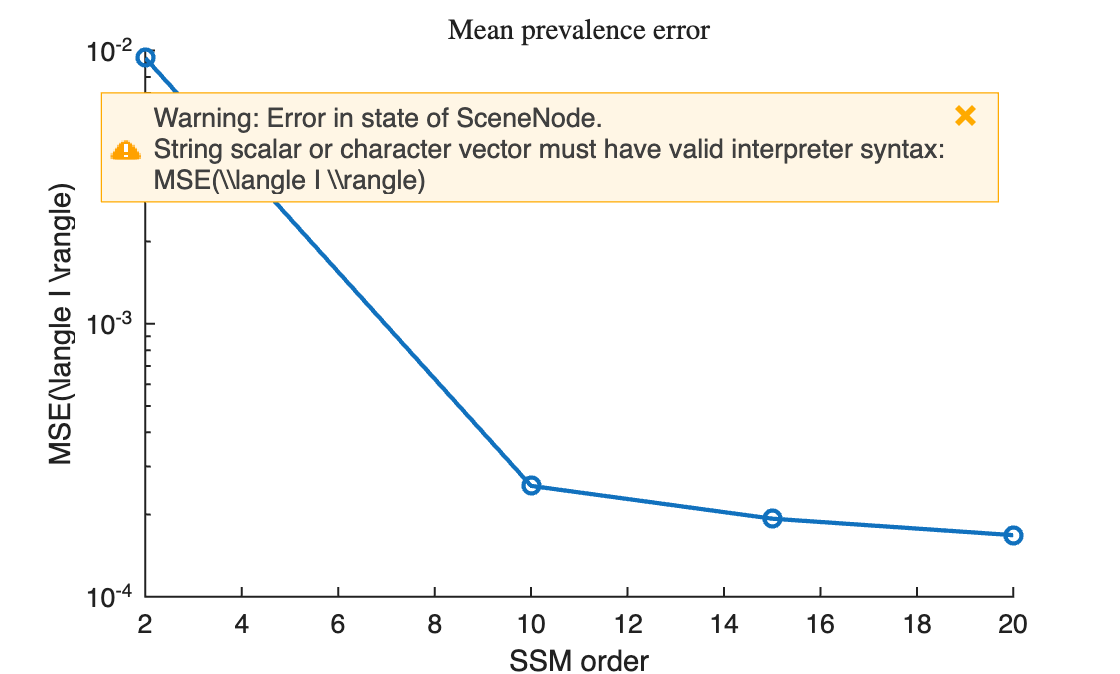

figure; hold on
plot(orders, mse_mean, 'o-', 'LineWidth',1.6, 'MarkerSize',6);
set(gca,'YScale','log'); 
xlabel('SSM order'); ylabel('MSE(\langle I \rangle)','Interpreter','latex');
title('Mean prevalence error','Interpreter','latex');
box off

**2. Node steady-state error vs degree**


$$\epsilon^{\mathrm{ss}}_i(o)
= \big|\,x^{\mathrm{ss}}_{i,\text{full}} - x^{\mathrm{ss}}_{i,\text{SSM}(o)}\,\big|.$$


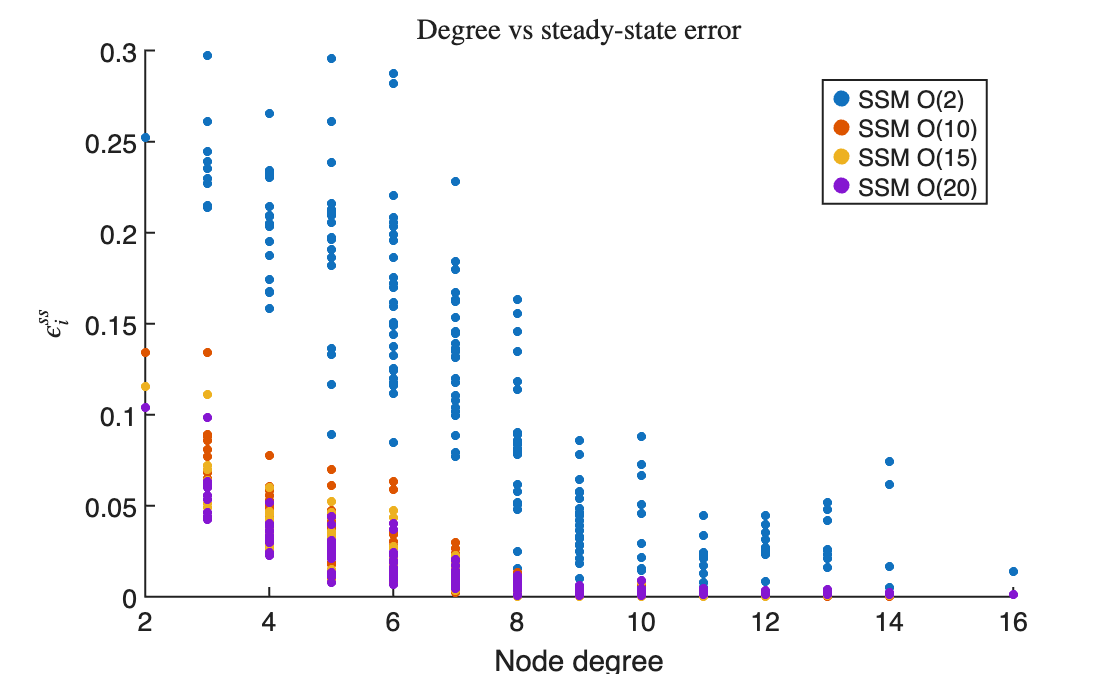

cols = lines(numel(orders));    
figure; hold on
for k = 1:numel(orders)
    scatter(deg_net, eps_ss(k,:), 12, cols(k,:), 'filled', ...
        'DisplayName', sprintf('SSM O(%d)', orders(k)));
end
xlabel('Node degree'); 
ylabel('$\epsilon_i^{ss}$','Interpreter','latex');
title('Degree vs steady-state error','Interpreter','latex');
legend('Location','best'); box off

**3. Distribution of node-wise steady-state errors**


$$\{\epsilon^{\mathrm{ss}}_i(o)\}_{i=1}^{N}
\quad\text{summarized per order } o.$$


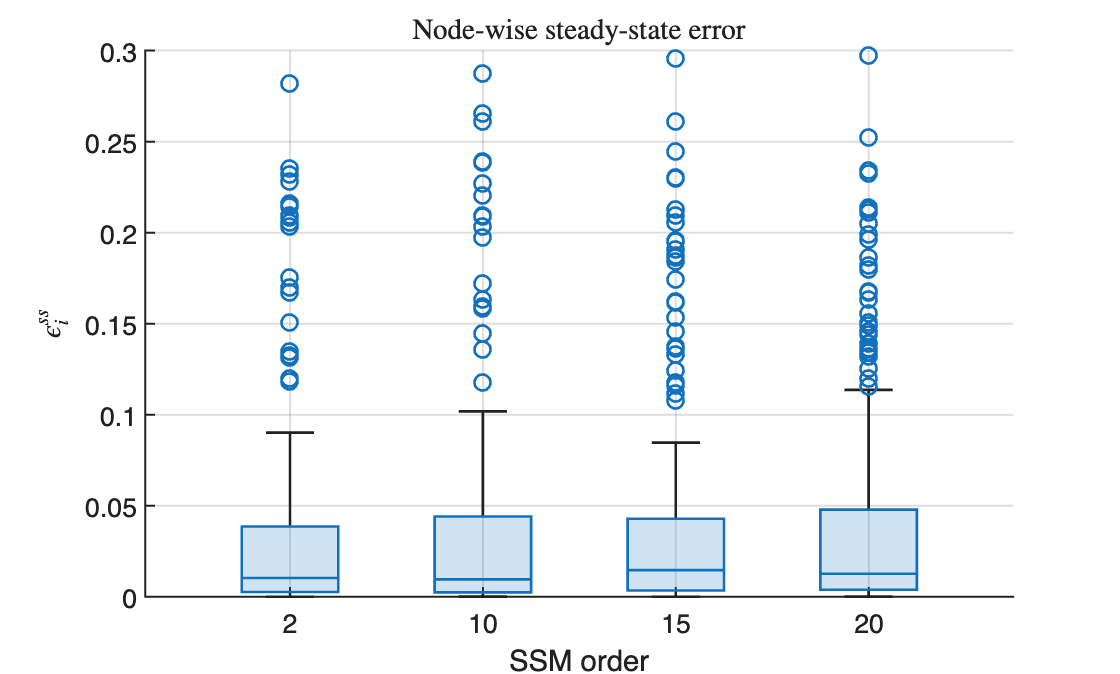

T = table(repelem(orders', N, 1), eps_ss(:), ...
          'VariableNames', {'Order','Err'});
figure
boxchart(categorical(T.Order), T.Err);
xlabel('SSM order'); ylabel('$\epsilon_i^{ss}$','Interpreter','latex');
title('Node-wise steady-state error','Interpreter','latex');
grid on

**4. Time-to-steady-state (TSS)**


$$\mathrm{TSS}_{i,\text{full}}
= \min\{t:\,|x_i(t)-x_{i,\text{full}}^{\mathrm{ss}}|<\tau\},\quad
\mathrm{TSS}_{i,\text{SSM}(o)}
= \min\{t:\,|x^{(o)}_i(t)-x_{i,\text{SSM}(o)}^{\mathrm{ss}}|<\tau\}.$$


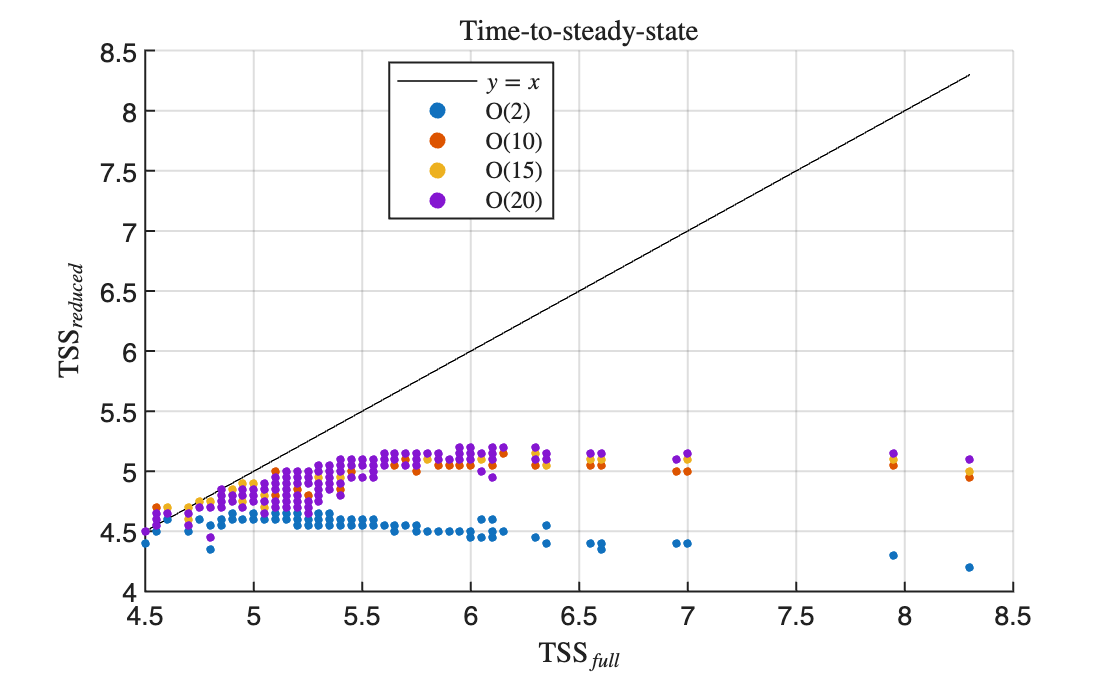

cols = lines(numel(orders));
figure; hold on
lims = [min(TSS_full), max(TSS_full)];
hRef = plot(lims, lims, 'k-', 'DisplayName','$y=x$'); 

for k = 1:numel(orders)
    scatter(TSS_full, TSS_red(k,:), 10, cols(k,:), 'filled', ...
        'DisplayName', sprintf('O(%d)',orders(k)));
end

xlabel('$\mathrm{TSS}_{full}$','Interpreter','latex');
ylabel('$\mathrm{TSS}_{reduced}$','Interpreter','latex');
title('Time-to-steady-state','Interpreter','latex');

legend('show','Interpreter','latex','Location','best');
grid on; box off

**5. Global MAE & spatial correlation**


$$\mathrm{MAE}(o) = \frac{1}{N}\sum_{i=1}^{N}\epsilon^{\mathrm{ss}}_i(o),
\qquad
\rho(o) = \mathrm{corr}\!\left(x^{\mathrm{ss}}_{\text{full}},\,x^{\mathrm{ss}}_{\text{SSM}(o)}\right).$$


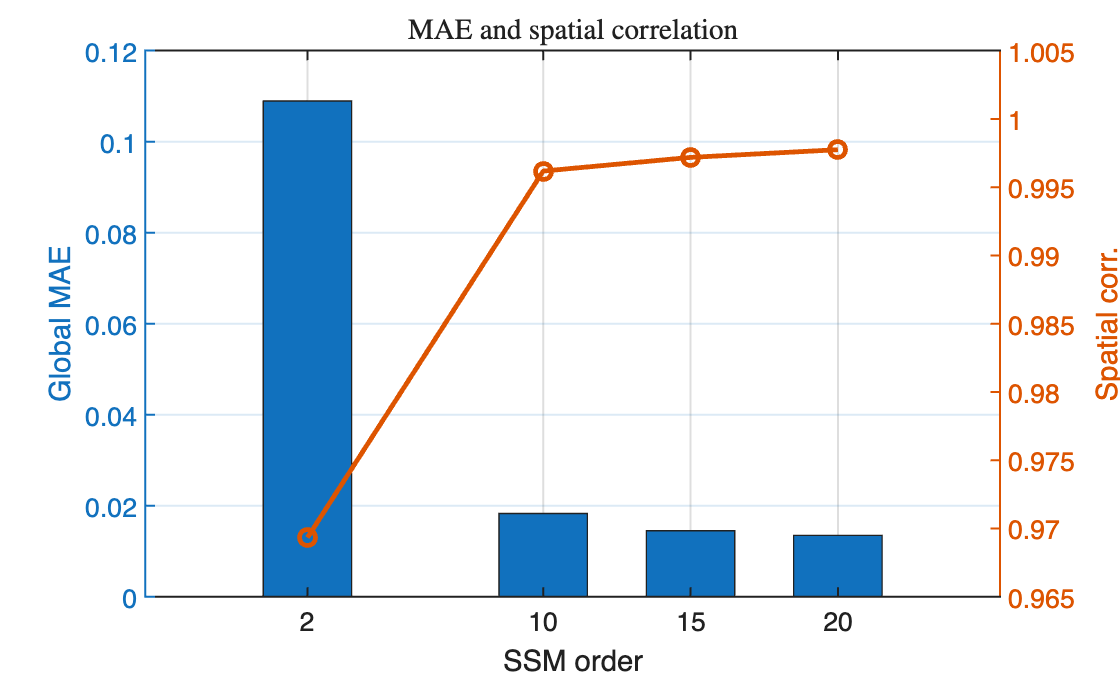

figure
yyaxis left
bar(orders, MAE_node, 0.6); ylabel('Global MAE');
yyaxis right
plot(orders, spatialCorr, '-o', 'LineWidth',1.8);
ylabel('Spatial corr.');
xlabel('SSM order'); 
title('MAE and spatial correlation','Interpreter','latex');
grid on

**6. Error surface (time × order)**


$$E_o(t) = \frac{1}{N}\sum_{i=1}^{N}\big|x_i(t)-x^{(o)}_i(t)\big|.$$


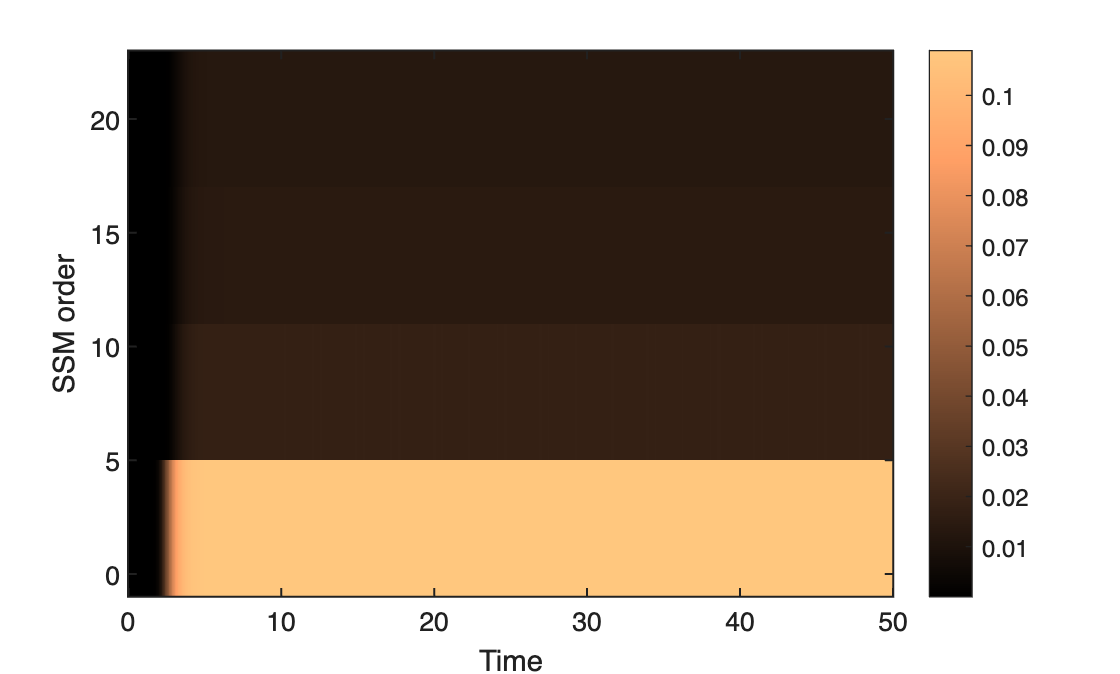

figure
imagesc(t_full, orders, err_surface); axis xy
xlabel('Time'); ylabel('SSM order');
colorbar; colormap(copper);

## (k) Save results

save('SIS_er.mat', 'W0','R0','A','beta','mu','z0_full','q0','tRef','zRef');

## (l) Local helpers

function [A, B, F] = build_model(adj, beta, mu)
    n = size(adj,1);
    B = eye(n);
    A = beta*adj - mu*B;
    idx = find(adj);
    [i,j] = ind2sub([n n], idx);
    subs = [i, i, j];
    vals = -beta * adj(idx);
    F2 = sptensor(subs, vals, [n, n, n]);
    F  = {F2};
end

function apply_pub_defaults(S)
    set(groot,'defaultAxesFontName',   S.FontName);
    set(groot,'defaultTextFontName',   S.FontName);
    set(groot,'defaultAxesFontSize',   S.BaseFS);
    set(groot,'defaultTextInterpreter','none');
    set(groot,'defaultAxesTickLabelInterpreter','none');
    set(groot,'defaultLegendInterpreter','none');
    set(groot,'defaultAxesLineWidth',  S.AxisLineWidth);
    set(groot,'defaultAxesTickDir',    'out');
    set(groot,'defaultAxesBox',        'off');
    set(groot,'defaultAxesTitleFontWeight','normal');
end

function name = pick_font(primary, fallback)
    f = listfonts; name = fallback;
    if any(strcmpi(f, primary)), name = primary; end
end

function plot_analytical_domain(appr_order, R_0)
    if appr_order < 1 || ~isstruct(R_0), warning('plot_analytical_domain: bad inputs'); return; end
    ord0   = floor(appr_order/2);
    ordVec = ord0:appr_order;
    nRuns  = numel(ordVec);
    cmap = flipud(gray(max(nRuns,2)));
    holdState = ishold; hold on;
    last_roots = [];
    run_idx = 1;
    for order = ordVec
        p = zeros(1, order+1);
        for j = 1:order
            if j <= numel(R_0) && isfield(R_0(j),'coeffs') && ~isempty(R_0(j).coeffs)
                crow = R_0(j).coeffs(1,:);
                nz   = crow(abs(crow) > 0);
                if ~isempty(nz), p(j+1) = real(nz(1)); end
            end
        end
        rts = roots(flip(p));
        last_roots = rts;
        if order < appr_order
            plot(real(rts), imag(rts), '.', 'Color', cmap(min(run_idx,size(cmap,1)),:), 'MarkerSize', 10, 'HandleVisibility','off');
        else
            plot(real(rts), imag(rts), 'm.', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Roots of $a(\rho)$', 'Color', 'm');
        end
        run_idx = run_idx + 1;
    end
    xlabel('Real part', 'Interpreter','latex');
    ylabel('Imaginary part', 'Interpreter','latex');
    legend('show', 'Interpreter','latex', 'Location','best');
    axis equal; box off;
    if ~isempty(last_roots)
        rho_med = median(abs(last_roots));
        sel     = abs(last_roots) > rho_med;
        if any(sel)
            rho = mean(abs(last_roots(sel)));
            if isfinite(rho) && rho > 0
                lim = 1.5 * rho; xlim([-lim, lim]); ylim([-lim, lim]);
            end
        end
    end
    if ~holdState, hold off; end
end